# Quantitative Methods for Finance

2025 Marina Dolfin

# **QMF2_2_Modelling_MonteCarloSimulations**

## Value at Risk Estimation via Monte Carlo Simulation of Return Distributions

**(A short theoretical background is provided at the end of the Live Script.)**

Value at Risk (VaR) measures the potential loss in portfolio value over a given time horizon and confidence level.

There are three main approaches to estimating VaR:

- **Parametric (Variance–Covariance)** — assumes normally distributed returns and computes VaR analytically from the mean and standard deviation.

- **Historical Simulation** — derives VaR directly from the empirical distribution of past returns, without distributional assumptions.

- **Monte Carlo Simulation** — generates many possible future return paths from a chosen stochastic model and evaluates VaR from the simulated distribution.

In this activity, we adopt the **Monte Carlo approach**, using simulated returns under a **Geometric Brownian Motion (GBM)** model to analyze the shape of future return distributions and assess **tail risk**.

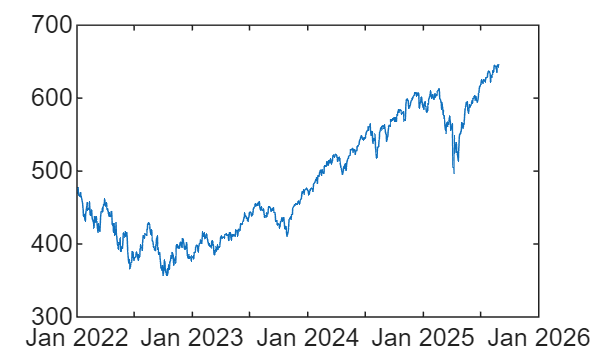


clear all

close all

symbol = 'SPY';                     % Stock symbol for the ETF SPY.
startDate = '01-Jan-2022';           % Start date
endDate = '28-Aug-2025';             % End date
interval = '1d';                     % Data interval ('1d', '1wk', '1mo')
fields = {'close'}; %{'open', 'high', 'low', 'close', 'volume'};  % Fields to retrieve

% Fetch data
stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields);



stock  = stockData.Close; %identify the stock of interest

plot(stockData.Date,stock) %plot the time trend

Data analysis: check for outliers

Use of the boxplot: values in red outside the whiskers are the outliers. Plot also the outliers together with the plot of returns (red circles in red) 

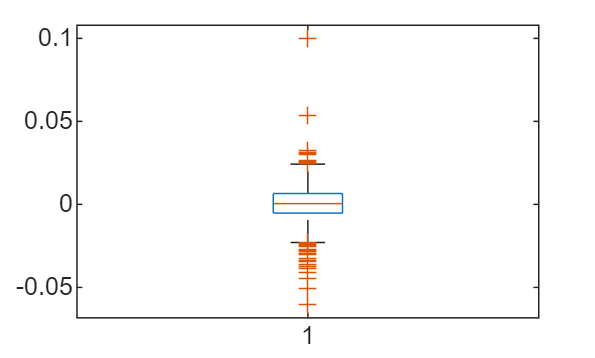


stockReturns=diff(log(stock));

boxplot(stockReturns)

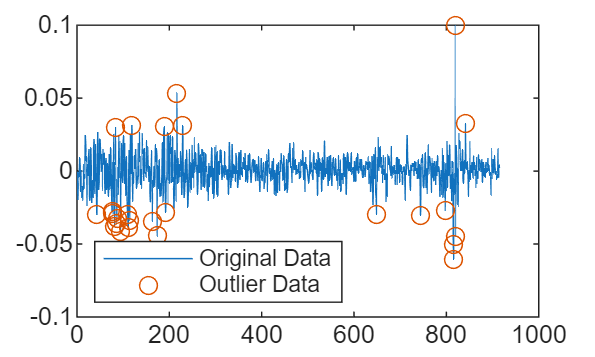



out =isoutlier(stockReturns);

x = 1: length(stockReturns);

plot(stockReturns)

hold on

scatter(x(out),stockReturns(out))

legend('Original Data', 'Outlier Data', 'Location', 'Southwest')
hold off

## Simulations

deltaT = 1;  %The interval of time is simply one day (with daily frequency)


As a first step you want to calculate all the stochastic factors for each simulation

and all the simulated days

sim_days = 30

sim_days = 30


numsim = 1000

numsim = 1000


S0 = stock(end)  %extract the value of the recorded last trading day of the stock of interest

S0 = 646.6300



mu = mean(stockReturns); 
sigma = std(stockReturns);


Remember the stochastic factor

# 
$$e^{\Big(\mu-\frac{\sigma^2}{2}\Delta t\Big)+\epsilon\sigma\sqrt{\Delta t}}$$


To make this follow the procedure: calculate the random numbers related to all the simulated days and the number of simulations


epsilon = randn(sim_days,numsim);

calculate the stochastic factors for all the days and simulations


factors = exp((mu-sigma^2/2)*deltaT + sigma *epsilon*sqrt(deltaT));


Now, you can multiply each factor by the stock price of the given day (starting from the last trading day for instance) to create a series of simulated prices.

Using matrices you can create a large number of such simulated paths.

Produce a row vector with all entries equal to the value of the last trading day of the stock of interest


lastPriceVector = S0*ones(1,numsim);


concatenate vertically the previously calculated vector to the matrix of stochastic factors


factors = [lastPriceVector;factors];


calculate the cumulative product using the vector of factors which was concatenated qith the value of the last trading day


paths = cumprod(factors);


Now I have simulated the closing prices of the stock for sim_days future days after the last recorded price

Each possible path is stored in an individual column of the paths matrix.

plot the simulations

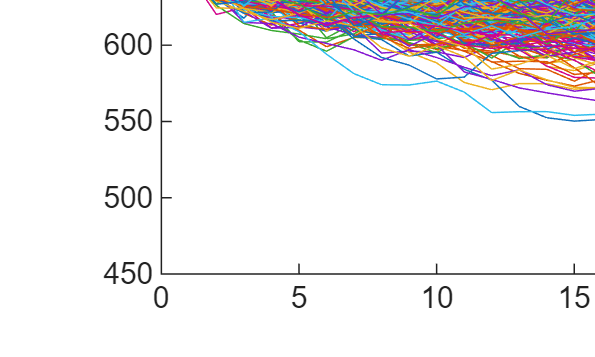


plot(paths)

Plot the simulations along with the historical prices in a different graphic window

first plot the historical prices

figure

plot(stockData.Date,stock)
hold on
futureDates = stockData.Date(end) +caldays(0:sim_days)

futureDates = 1×31 datetime array
   27-Aug-2025 13:30:00   28-Aug-2025 13:30:00   29-Aug-2025 13:30:00   30-Aug-2025 13:30:00   31-Aug-2025 13:30:00   01-Sep-2025 13:30:00   02-Sep-2025 13:30:00   03-Sep-2025 13:30:00   04-Sep-2025 13:30:00   05-Sep-2025 13:30:00   06-Sep-2025 13:30:00   07-Sep-2025 13:30:00   08-Sep-2025 13:30:00   09-Sep-2025 13:30:00   10-Sep-2025 13:30:00   11-Sep-2025 13:30:00   12-Sep-2025 13:30:00   13-Sep-2025 13:30:00   14-Sep-2025 13:30:00   15-Sep-2025 13:30:00   16-Sep-2025 13:30:00   17-Sep-2025 13:30:00   18-Sep-2025 13:30:00   19-Sep-2025 13:30:00   20-Sep-2025 13:30:00   21-Sep-2025 13:30:00   22-Sep-2025 13:30:00   23-Sep-2025 13:30:00   24-Sep-2025 13:30:00   25-Sep-2025 13:30:00   26-Sep-2025 13:30:00


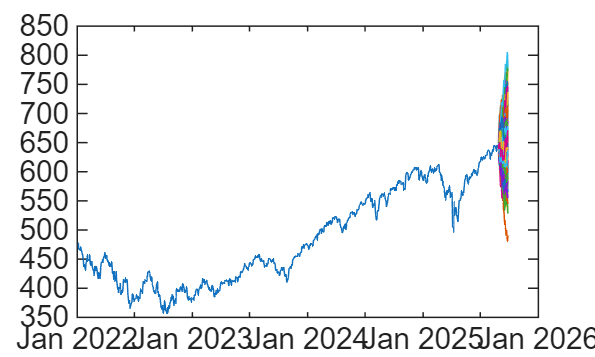

plot(futureDates',paths)
hold off

**Focus on the last trading days**

figure

stock_focus=stock(end-50:end);
datesFocus=stockData.Date(end-50:end)

datesFocus = 51×1 datetime array
   16-Jun-2025 13:30:00
   17-Jun-2025 13:30:00
   18-Jun-2025 13:30:00
   20-Jun-2025 13:30:00
   23-Jun-2025 13:30:00
   24-Jun-2025 13:30:00
   25-Jun-2025 13:30:00
   26-Jun-2025 13:30:00
   27-Jun-2025 13:30:00
   30-Jun-2025 13:30:00
   01-Jul-2025 13:30:00
   02-Jul-2025 13:30:00
   03-Jul-2025 13:30:00
   07-Jul-2025 13:30:00
   08-Jul-2025 13:30:00
   09-Jul-2025 13:30:00
   10-Jul-2025 13:30:00
   11-Jul-2025 13:30:00
   14-Jul-2025 13:30:00
   15-Jul-2025 13:30:00
   16-Jul-2025 13:30:00
   17-Jul-2025 13:30:00
   18-Jul-2025 13:30:00
   21-Jul-2025 13:30:00
   22-Jul-2025 13:30:00
   23-Jul-2025 13:30:00
   24-Jul-2025 13:30:00
   25-Jul-2025 13:30:00
   28-Jul-2025 13:30:00
   29-Jul-2025 13:30:00


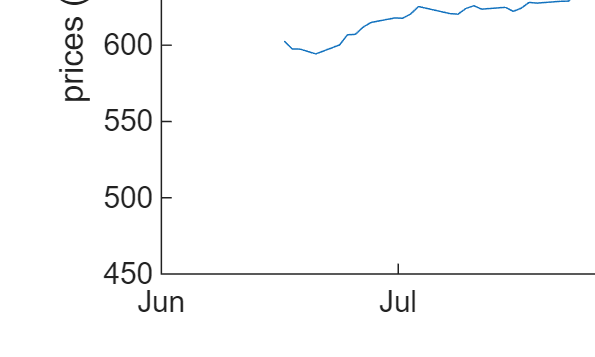

plot(datesFocus,stock_focus)


ylabel('prices (US dollars)')
hold on
plot(datesFocus(end)+caldays(0:sim_days),paths)

hold off

## Evaluate VaR of simulated prices

#### Extract the simulated final prices

finalPrices = paths(end,:);


Calculate the log returns of each path over the simulated days by subtracting the log of the initial price (S0) from the log of the final prices. 

Store the returns vector

 

possibleReturns = log(finalPrices)-log(S0);


plot the histogram of returns with a given number of bins

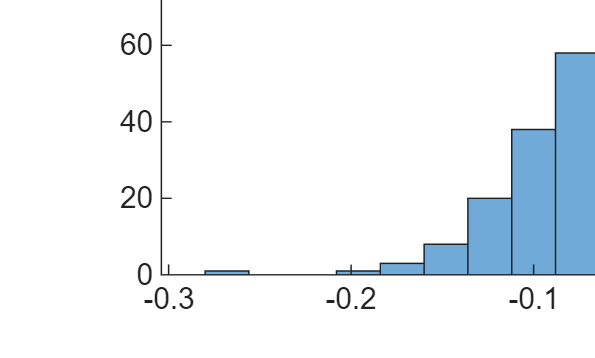

figure
histogram(possibleReturns,20)

 Calculate the 5% VaR, i.e. the fifth percentile of the possible returns (the function prctile(v,p) calculate the p percentile of the values in the vector v

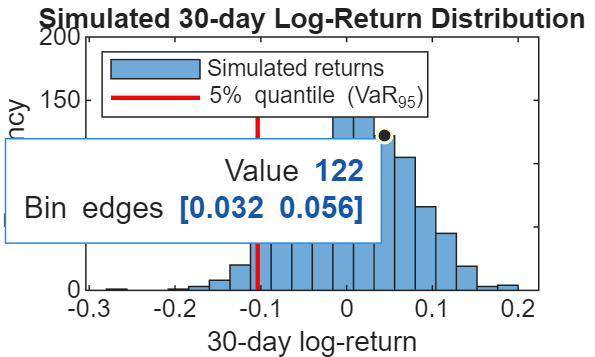

 
% 30-day cumulative returns (log and simple)
finalPrices  = paths(end,:);
logR_30      = log(finalPrices) - log(S0);     % log-return over horizon
simpleR_30   = finalPrices./S0 - 1;            % (equivalent for VaR)

% 95% VaR on returns (positive number); q5 is the left tail quantile
q5_log       = prctile(logR_30, 5);
VaR95_ret    = -q5_log;                        % report as positive
VaR95_money  = S0 * VaR95_ret;                 % monetary VaR

% Plot histogram + vertical line at the 5th percentile (negative value)
figure; histogram(logR_30, 20); hold on
plot([q5_log q5_log], ylim, 'r', 'LineWidth', 1.5);
title('Simulated 30-day Log-Return Distribution');
xlabel('30-day log-return'); ylabel('Frequency');
legend('Simulated returns', '5% quantile (VaR_{95})', 'Location', 'northwest')
hold off

function stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields)
% fetchYahooFinanceData Fetches historical stock data from Yahoo Finance.
%
%   stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields)
%
%   Parameters:
%       symbol     - Stock symbol as a string (e.g., 'AAPL').
%       startDate  - Start date as a string or datetime ('dd-mmm-yyyy' format).
%       endDate    - End date as a string or datetime ('dd-mmm-yyyy' format).
%       interval   - Data interval: '1d' (daily), '1wk' (weekly), '1mo' (monthly).
%       fields     - Cell array of strings -i.e.curly brackets needed to
%       enter input, specifying data fields to retrieve, one or more
%                    Valid fields: 'open', 'close', 'high', 'low',
%                    'volume'. e.g.{'open', 'high', 'low', 'close', 'volume'}, 
%
%   Returns:
%       stockData  - Table containing the date and requested data fields.

    % Validate inputs
    if nargin < 5
        error('All five arguments (symbol, startDate, endDate, interval, fields) are required.');
    end

    % Convert dates to datetime if necessary
    if ischar(startDate) || isstring(startDate)
        startDate = datetime(startDate, 'InputFormat', 'dd-MMM-yyyy');
    end
    if ischar(endDate) || isstring(endDate)
        endDate = datetime(endDate, 'InputFormat', 'dd-MMM-yyyy');
    end

    % Validate interval
    validIntervals = {'1d', '1wk', '1mo'};
    if ~ismember(interval, validIntervals)
        error('Invalid interval. Choose from ''1d'', ''1wk'', or ''1mo''.');
    end

    % Convert dates to UNIX timestamps
    startNum = posixtime(datetime(startDate));
    endNum = posixtime(datetime(endDate));

    % Construct the URL
    url = ['https://query1.finance.yahoo.com/v8/finance/chart/' symbol ...
           '?period1=' num2str(floor(startNum)) '&period2=' num2str(floor(endNum)) '&interval=' interval];

    % Set web options with a user-agent header to mimic a browser
    options = weboptions('ContentType', 'json', 'UserAgent', 'Mozilla/5.0');

    % Fetch data
    try
        data = webread(url, options);
    catch ME
        error('Failed to retrieve data: %s', ME.message);
    end

    % Check for errors in response
    if isempty(data.chart.result) || ~isempty(data.chart.error)
        error('Failed to retrieve data. Please check the stock symbol and date range.');
    end

    % Extract the result
    result = data.chart.result;
    if iscell(result)
        result = result{1};
    elseif isstruct(result) && numel(result) > 1
        result = result(1);
    end

    % Extract timestamps
    if isfield(result, 'timestamp')
        timestamps = result.timestamp;
    else
        error('No timestamp data available.');
    end

    % Convert timestamps to datetime
    dates = datetime(timestamps, 'ConvertFrom', 'posixtime', 'TimeZone', 'UTC');

    % Access indicators
    if isfield(result, 'indicators') && isfield(result.indicators, 'quote')
        quote = result.indicators.quote;
        if iscell(quote)
            quote = quote{1};
        elseif isstruct(quote) && numel(quote) > 1
            quote = quote(1);
        end
    else
        error('No quote data available.');
    end

    % Initialize table with dates
    stockData = table(dates, 'VariableNames', {'Date'});

    % Ensure fields are in lowercase
    fields = lower(fields);

    % Valid fields in the data
    validFields = fieldnames(quote);

    % For each requested field, extract the data
    for i = 1:length(fields)
        field = fields{i};
        if ismember(field, validFields)
            fieldData = quote.(field);
            fieldData = fieldData(:);  % Ensure column vector
            % Handle missing data
            if length(fieldData) < length(dates)
                fieldData(end+1:length(dates)) = NaN;
            elseif length(fieldData) > length(dates)
                fieldData = fieldData(1:length(dates));
            end
            % Append to table with capitalized field name
            stockData.(capitalizeFirstLetter(field)) = fieldData;
        else
            warning('Field "%s" is not available in the data.', field);
            % Fill with NaNs if field is missing
            stockData.(capitalizeFirstLetter(field)) = NaN(height(stockData), 1);
        end
    end

    % Remove rows where all data fields are NaN
    dataFields = stockData.Properties.VariableNames(2:end);
    validRows = any(~isnan(stockData{:, dataFields}), 2);
    stockData = stockData(validRows, :);

    % Reset the datetime to remove time zone information
    stockData.Date.TimeZone = '';

end

function outStr = capitalizeFirstLetter(inStr)
% Helper function to capitalize the first letter of a string
    outStr = lower(inStr);
    if ~isempty(outStr)
        outStr(1) = upper(outStr(1));
    end
end


## When using the Value-at-Risk measure, we are interested in making a statement of the following form:

## "We are X percent certain that we will not lose more than V pounds in time T"

## The variable V is the VaR of the portfolio. It is a function of two parameters: the time horizon T and the confidence level X percent. 

## It is the loss level during a time period of length T that we are X% certain will not be exceeded.

## For example, when T is five days and X=97, VaR is the loss at the 3rd percentile of the distribution of gains over the next five days. 

## Alternatively, it is the loss at the 97th percentile of the distribution of losses over the next five days.  More generally, when the distribution of gains is used, VaR is equal to minus the gain at the (100-X)th percentile of the distribution.

## 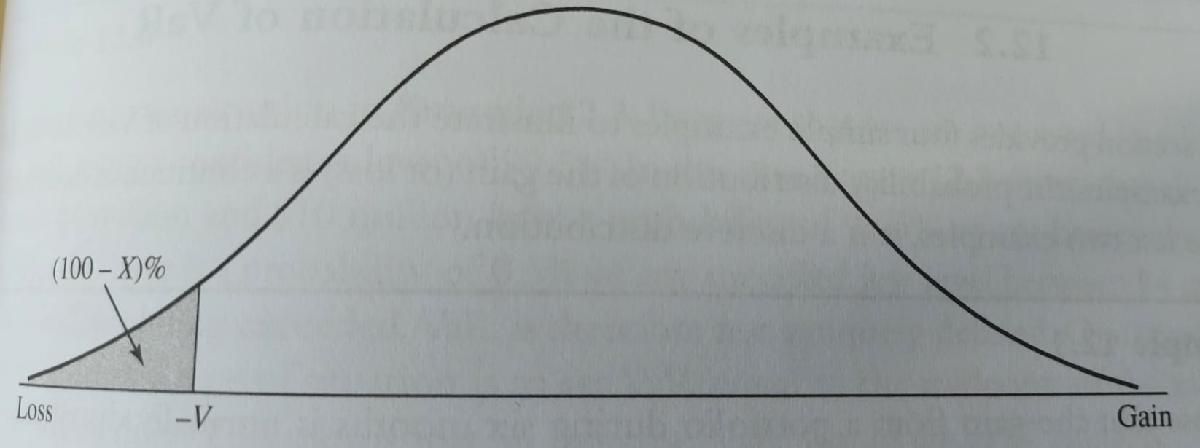

## Example

## Suppose that the gain from a portfolio during six months is normally distributed with a mean of £2 m and a standard deviation of £10 m. The 1-percentile point of the normal distribution is

## 
$$\textsterling 2 m-2.326*\textsterling 10 m = - \textsterling 21.3 m$$


## VaR = norminv(0.01,2,10)

## VaR is an attractive measure, because it is easy to understand. 

## It asks the simple question "How bad can things get?" 

## However, when VaR is used in an attempt to limit the risks taken by a trader, it can lead to undesiderable results. 

## Suppose that a bank tells a trader that the one-day 99% VaR of the trader's portfolio must be limited to £10 m. The trader can contruct a portfolio where there is a 99.1% chance that the daily loss is less then £10 m, and a 0.9% chance that is £500 m. 

## The trader is satysfying the risk limits imposed by the bank, but is clearly taking unacceptable risks. 

## 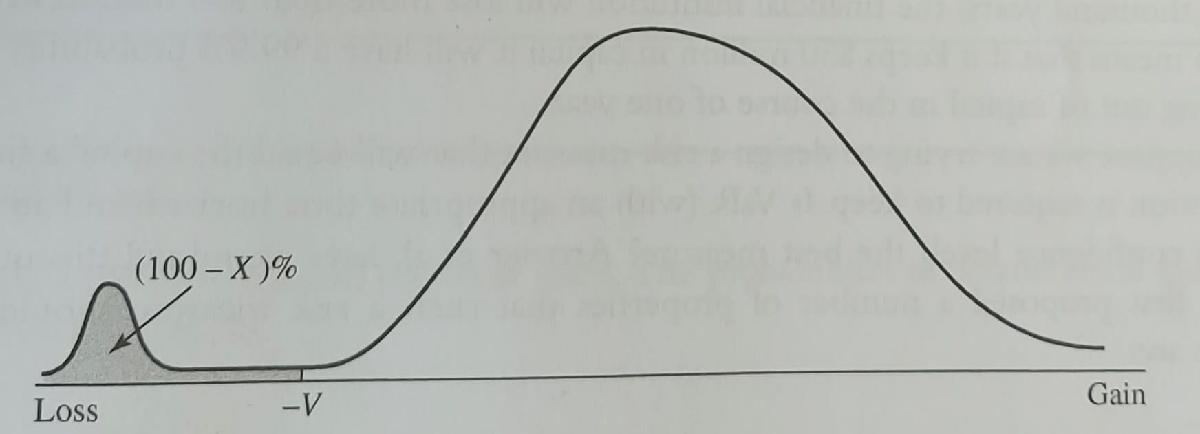

## Even if the two Var for the two distributions are the same, of course the portfolio related to the second distribution is much riskier the the first one.

## It should moreover be noticed that a probability distribution like the one above is not that unusual as one might think.

## Modelling uncertainty

## We assume that a variable, say the price of a stock or a commodity, can be modelled as a random variable, whose probability distribution is known, possibly inferred from available data (we are using only exogeneous uncertainty). 

## The simplest model of uncertainty is the binomial model. 

## We know the current price $S_0$ at time t=0, and we assume that the price $S_1$, at some future time instant t=1, can take only two values.

## 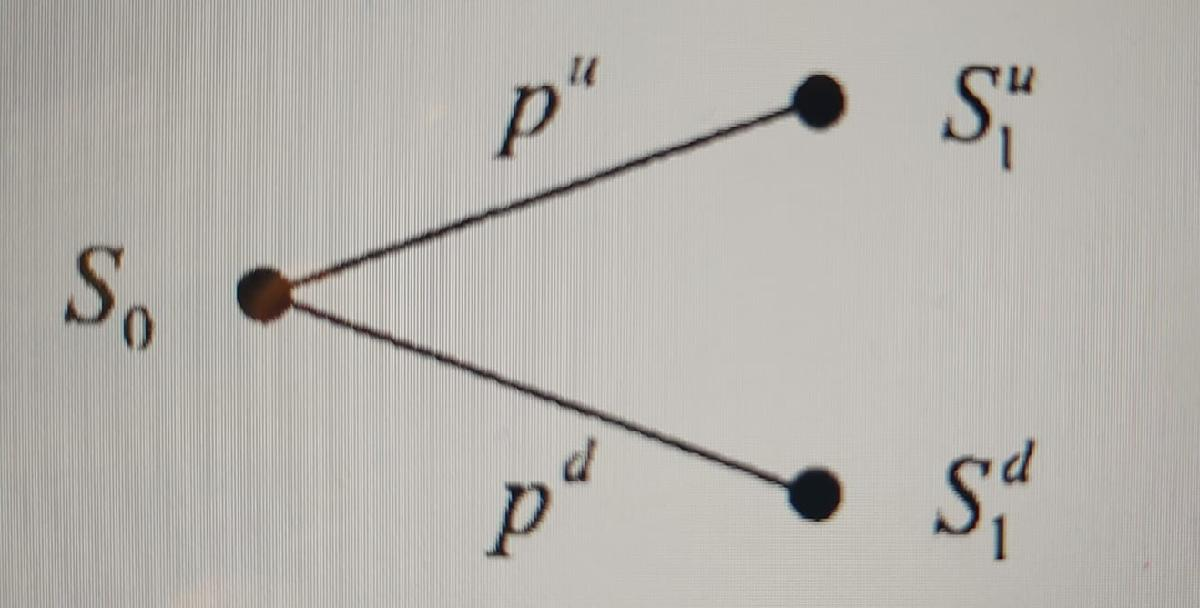

## A common choice is to represent uncertainty by a multiplicative shock, i.e. $S_1^u=uS_0$ and $S_1^d=dS_0$, where the letters u and d suggest 'up' and 'down', respectively (hence, d<u). 

## Apparently, this model is very crude, but it is the building block of very useful models.

## A more refined model can be built by allowing for more then just two future states. 

##  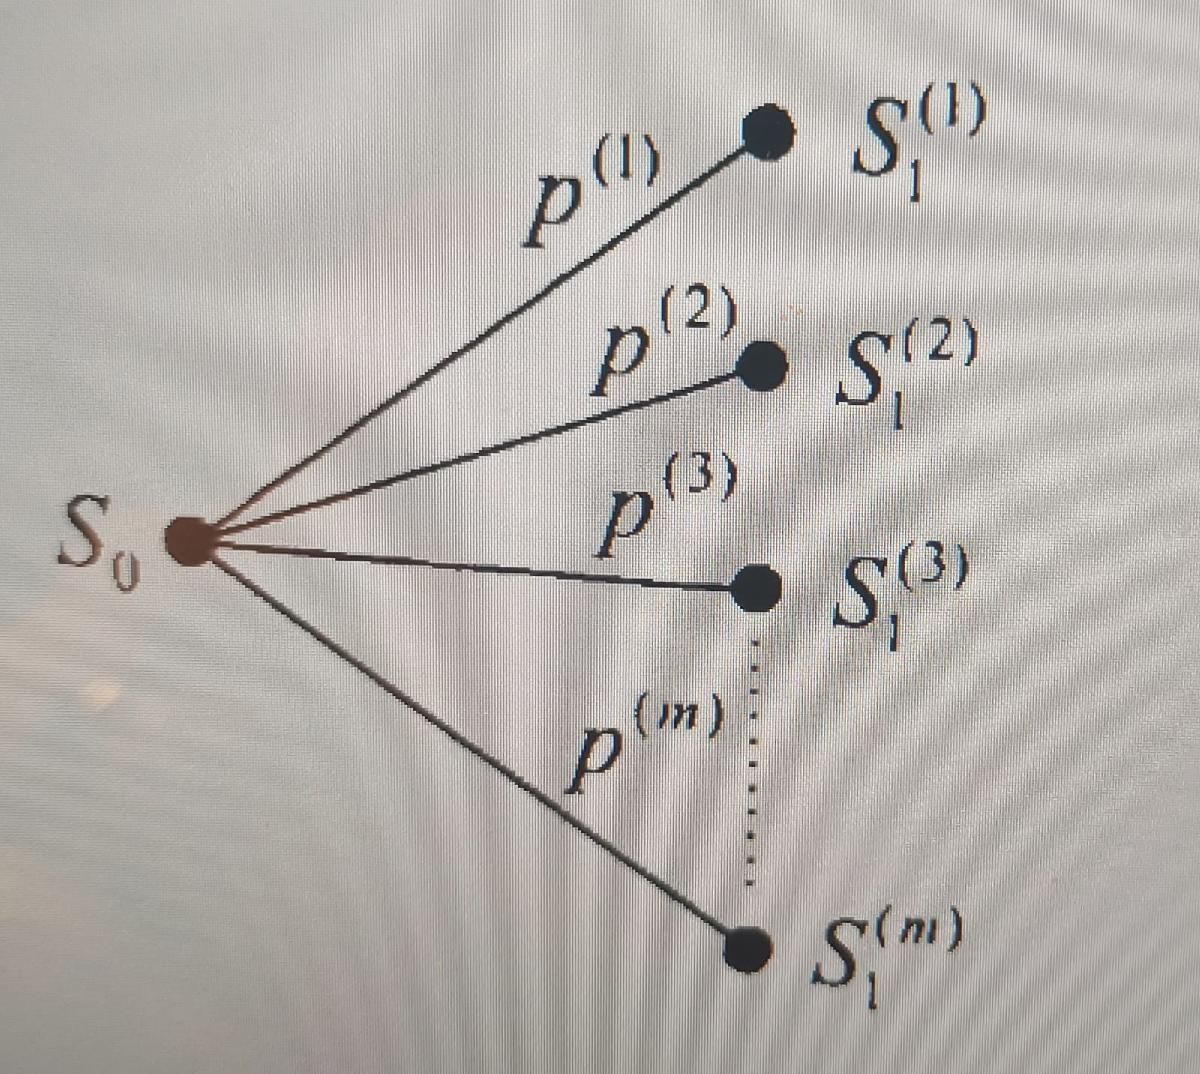

## Moreover, one can consider a discrete-state, discrete-time, multiperiod model

## 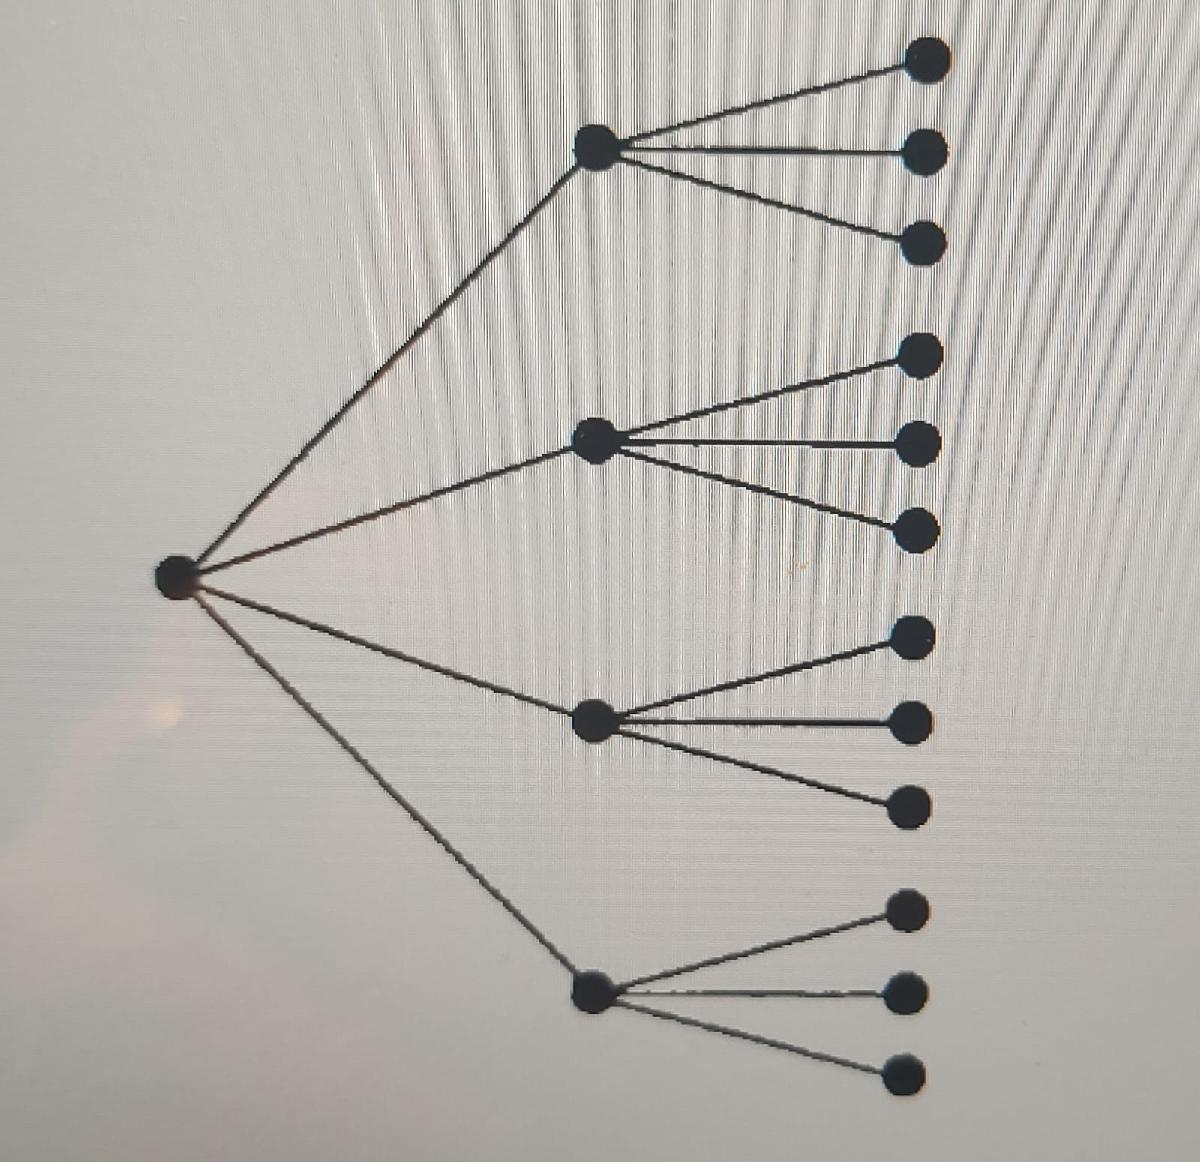

## Sometimes, to keep computational effort limited, we prefer using a recombining lattice.

## 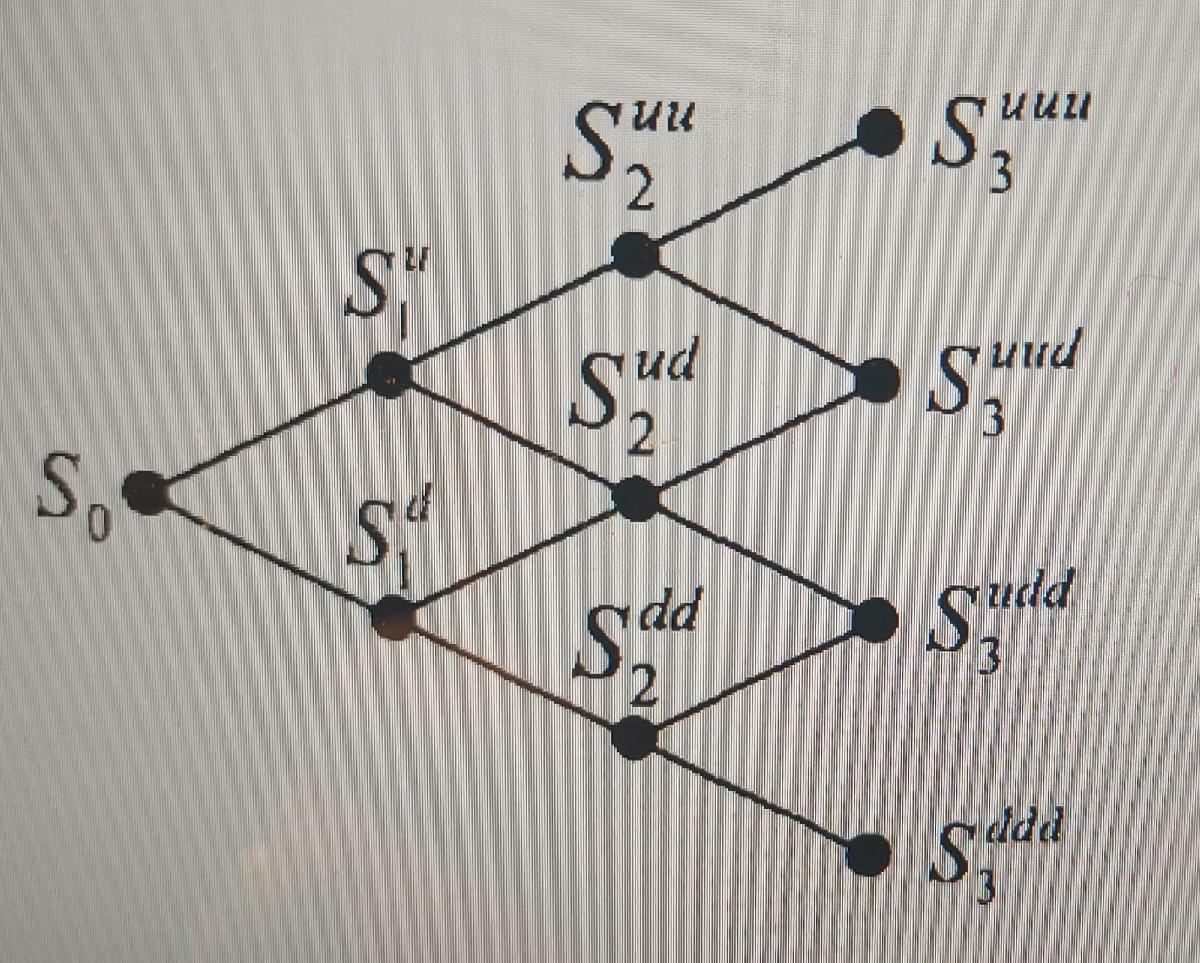

## Since $udS_0=duS_0$, we see that an up-jump followed by a down-jump is the same as a down-jump followed by an up-jump. 

## This means also assuming that the multiplicative shocks are always the same, which makes sense if the process is stationary and time step is constant.

## Sometimes, it is convenient to model uncertainty using instead a continuous distribution, such as the normal. 

## If we think of prices, a continuous distribution is certainly an idealization, since no price is quoted with too many decimal digits. 

## By the same token, we may also resort to continuous-time models, which may be thought of as the limit of a discrete-time model when the time step tends to zero.

## In this case, the usual building block is the Wiener process W(t), that can be considered as the continuous-time limit of a random walk described by a binomial lattice. 

## Geometric Brownian Motion (GBM)

## The standard Wiener process is a useful building block, but it cannot be directly used to model stock prices or interest rates, since (among other issues) it may take negative values. 

## To that aim, we introduce a powerful modelling framework to describe continuous - state, continuous-time processes. Informally, we talk about stochastic differential equations. 

## If we want to write a stochastic differential equation modelling the random return of an asset, we might consider the following modification of the generalized Wiener process:

## 
$$\frac{d S(t)}{S(t)}=\mu dt+\sigma dW(t)$$


## One can think then to that as the differential of log-price, $d\,log\,S_t$ and integrate it directly

## 
$$log\, S(t) -log\,S(0) =\Big( \mu-\frac{\sigma^2}{2}\Big)t+\sigma W(t)$$


## By recalling that $W_t$ has a normal distribution and can be written as $W_t =\epsilon\sqrt t$ with $\epsilon\sim N(0,1)$, we can rewrite the solution in terms of $S_t$ as

## 
$$S(t)=S(0)e^{\Big(\mu-\frac{\sigma^2}{2}\Big)t+\epsilon\sigma\sqrt{t}\Big)$$


## On the one hand, this shows that prices, according to the Geometric Brownian motion model, are log-normally distributed and cannot take negative values.

## On the other hand, now we have a way to generate sample paths, based on a discretization of a prescribed time horizon into time periods of length $\Delta t$.

## A brief note: relation with option pricing. Consider a vanilla option like a European-style call option written on a nondividend paying stock, whose price S(t) follows a geometric Brownian motion. Since increments in the driving Wiener process are independent, we may say that future history does not depend on the past. And we may also show that the value of the option at a time t before maturity will depend only on time (more precisely, time to maturity) and current price of the underlying.

## This leads to the Black-Scholes model (but this is another story...).

## Discretization and Monte Carlo approach

## When discretizing time, you simulate the stock price at time $t+\Delta t$ (tomorrow) by 

## 
$$S(t+\Delta t)=S(t)e^{\Big(\mu-\frac{\sigma^2}{2}\Big)\Delta t+\epsilon\sigma\sqrt{\Delta t}\Big)$$


## where

## $\mu$ mean return

## $\sigma$standard deviation of returns

## $\epsilon$ random variable

## The above formula generates sample paths.

## Note on simple vs log returns

When simulating price dynamics, two related but distinct measures of returns are commonly used: **simple returns** and **logarithmic (log) returns**.

The simple return measures the percentage change in price between two periods, while the log return is the natural logarithm of the price ratio.

For small price movements, they are numerically close, but log returns are additive over time and follow a Normal distribution under the **Geometric Brownian Motion (GBM)** model.

For this reason, GBM simulations are typically generated in terms of log returns.

In contrast, **Value at Risk (VaR)** is often reported in terms of *simple returns* or *monetary losses*, because these are easier to interpret.

Once the simulated log returns are obtained, they can be converted to simple returns to express losses as percentages or absolute amounts.

For example, if the 5th percentile of simulated log returns is –0.05, the equivalent simple return is e−0.05−1≈−4.88%e^{-0.05} - 1 \approx -4.88\%e−0.05−1≈−4.88%.

If the current portfolio value is $100,000, this corresponds to a 95% VaR of $4,880.

## References:

## [1] Glasserman, P. Monte Carlo Methods in Financial Engineering. Springer-Verlag, New York, 2004.

## [2] Hull, J. C. Options, Futures, and Other Derivatives. 5th edition, Englewood Cliffs, NJ: Prentice Hall, 2002